addpath('/usr/local/freesurfer/stable6/fsfast/toolbox')

CONV_TYPE = 'full'

CONV_TYPE = 'full'

NOISE = 3

NOISE = 3

NRUNS = 3

NRUNS = 3

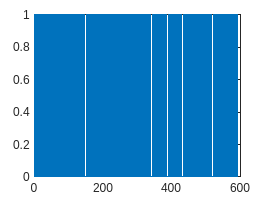



% Load EEG spike train for this network of this run of this subject
eeg = load('/local_mount/space/ursa/4/users/HDRmodeling/EEGspikeTrains/DAN5/s06_137-r1.par');
eeg(isnan(eeg)) = 0;
neeg = length(eeg);
fsample_eeg = 20; % Hz
teeg = [0:neeg-1]'/fsample_eeg;
plot(teeg,eeg)

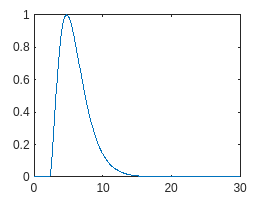

% Ideal fMRI HRF response
% time sampled at EEG rate at a long enough window (30sec) to
% capture the response
thrf = [0:600]/fsample_eeg; 
% Parameters of the parametric HRF model
delta = 2.25; % sec
tau = 1.25;
alpha = 2;
% Ideal HRF waveform
hrf = fmri_hemodyn(thrf,delta,tau,alpha);
plot(thrf,hrf)

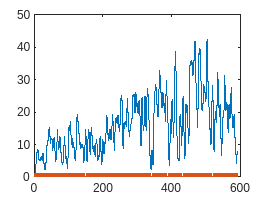


% This is the ideal fMRI waveform assuming these parameters
% sampled at the EEG
hrfeeg = conv(eeg,hrf,CONV_TYPE);
hrfeeg = hrfeeg(1:length(eeg));
plot(teeg,hrfeeg,teeg,eeg)

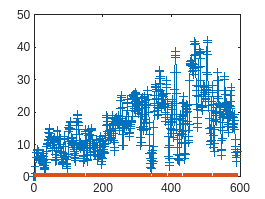


% Down-sample to fMRI sample rate
TR_fmri = 800; % msec
r_fmri = round(fsample_eeg*800/1000); % 16 EEG points for each fMRI point
tfmri = teeg(1:r_fmri:end);
hrfeeg_fmri = hrfeeg(1:r_fmri:end);
nfmri = length(tfmri);

plot(tfmri,hrfeeg_fmri,'+-',teeg,eeg)

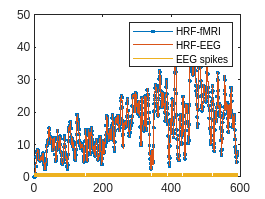


plot(tfmri,hrfeeg_fmri,'.-',teeg,hrfeeg,teeg,eeg)
legend('HRF-fMRI','HRF-EEG','EEG spikes')

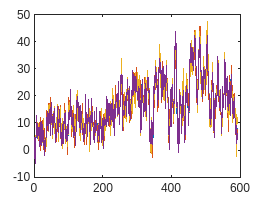


randn('state',53); % force noise to be the same in each iteration

% Simulate a raw fMRI waveform for now
fmri = hrfeeg_fmri + NOISE*randn(nfmri,NRUNS); 
plot(tfmri,hrfeeg_fmri,tfmri,fmri);

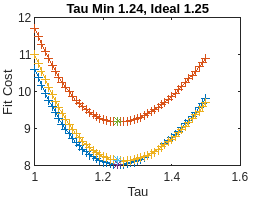


% Brute force search of tau over these values
% We know the ideal value is the value of tau above, 
% now let's see if we can find it.
taulist = [1:.01:1.5];
ntau = length(taulist);
rvarlist = zeros(ntau,NRUNS);
pvarlist = zeros(ntau,NRUNS);
fvarlist = zeros(ntau,NRUNS);
cesvarlist = zeros(ntau,NRUNS);
cesvarvarlist = zeros(ntau,NRUNS);
rvarmin = 10e10;
taumin = 0;
for nthtau = 1:ntau
  % Go through the process again with this tau
  tau_test = taulist(nthtau);
  hrf_test = fmri_hemodyn(thrf,delta,tau_test,alpha);  
  hrfeeg_test = conv(eeg,hrf_test,CONV_TYPE);
  hrfeeg_test = hrfeeg_test(1:length(eeg));
  hrfeeg_fmri_test = hrfeeg_test(1:r_fmri:end);
  % Fit this time course to raw fMRI to waveform with a GLM
  % beta = inv(X'*X)*X'*fmri; yhat = X*beta; residual = fmri-yat; residual
  % variance = std(residual). Same effect as doing the correlation
  % but residual variance is a cost we want to minimize rather than
  % a correlation to maximize
  X = [ones(nfmri,1) hrfeeg_fmri_test];
  [beta_test, rvar_test] = fast_glmfit(fmri,X);
  [F, p, ces, cesvar] = fast_fratio(beta_test, X, rvar_test, [1 0]);
  if(rvarmin > rvar_test)
    % Keep track of the minimum cost and the corresponding 
    rvarmin = rvar_test;
    taumin = tau_test;
  end
  rvarlist(nthtau,:) = rvar_test;
  pvarlist(nthtau, :) = p;
  fvarlist(nthtau, :) = F;
  cesvarlist(nthtau, :) = ces;
  cesvarvarlist(nthtau, :) = cesvar;
end

% Where is the tau of the minimum variance and how close to ideal?
plot(taulist,rvarlist,'+-',taumin,rvarmin,'*')
xlabel('Tau')
ylabel('Fit Cost');
title(sprintf('Tau Min %g, Ideal %g',taumin,tau));

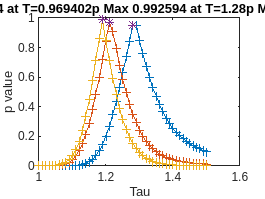


[m,i] = max(pvarlist);
plot(taulist,pvarlist,'+-', taulist(i), m, '*')
xlabel('Tau');
ylabel('p value');
title(sprintf('p Max %g at T=%g',m,taulist(i)));

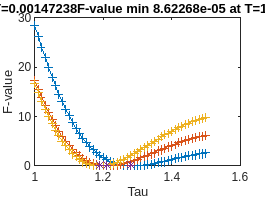


[m,i] = min(fvarlist);
plot(taulist,fvarlist,'+-', taulist(i), m, '*')
xlabel('Tau');
ylabel('F-value');
title(sprintf('F-value min %g at T=%g',m,taulist(i)));

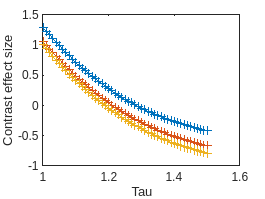


plot(taulist, cesvarlist, '+-')
xlabel('Tau');
ylabel('Contrast effect size');

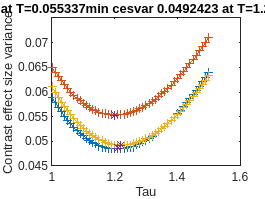


[m,i] = min(cesvarvarlist);
plot(taulist, cesvarvarlist, '+-', taulist(i), m, '*')
xlabel('Tau');
ylabel('Contrast effect size variance');
title(sprintf('min cesvar %g at T=%g',m,taulist(i)));